# Lecture 1 Practice - Solution

In this practice, you will use either a cell or structure array to store a database of classes taken by student X while at Stanford University.  Subsequently, the data structure will be used to compute the Grade Point Average (GPA) and other measures of academic performance for student X.

Files provided:

*courses.txt*

*read_courses.m*

*make_course_struct.m*

### **1.**

Loads the contents of *courses.txt* into a **cell array** using the provided function `read_courses`

g = read_courses('courses.txt');

Content of `g`:

- `g{i,1} `- cell array for course number (cross-listings not included)

- `g{i,2}` - string containing course title

- `g{i,3}` - string containing term course was taken

- `g{i,4}` - double containing number of units

- `g{i,5}` - string specifying whether pass/not pass or letter grade

- `g{i,6}` - string containing grade

g{end,:}

ans = 'CME 356'

ans = 'FNCTNL ANALYSIS FINITE ELEMENT'

ans = '2012-2013 Winter'

ans = 3

ans = 'Letter (ABCD/NP)'

ans = 'A'

### **2.**

Parses the text in the cell array to a more useful form in a **structure array** using the provided function `make_course_sruct`. What are the fields in the structure?

courses = make_course_struct(g);
courses(end)

ans = struct with fields:
       department: 'CME'
       course_num: 356
             type: 'L'
            grade: 'A'
       grad_units: 3
        gpa_units: 3
      gpa_credits: 4
          quarter: 'Winter'
             year: 2013
    academic_year: 2
    course_letter: []
            units: 3


### **3. **

Change the struct to a **table** using struct2table function

courses_tbl = struct2table(courses)

courses_tbl = 31×12 table
    department    course_num    type    grade    grad_units    gpa_units    gpa_credits    quarter     year    academic_year    course_letter    units
    __________    __________    ____    _____    __________    _________    ___________    ________    ____    _____________    _____________    _____

    'AA'             210        'L'     'B+'         3             3            3.3        'Autumn'    2013          3               'A'           3  
    'AA'             214        'L'     'C+'         3             3            2.3        'Winter'    2014     

Make the quarter and department categorical

courses_tbl.quarter = categorical(courses_tbl.quarter);
courses_tbl.department = categorical(courses_tbl.department);

Use a csv-file for sharing the data

writetable(courses_tbl,"coursesTable.csv")

### **4.**

Workflow with `readtable`

t = readtable("coursesTable.csv","TextType","string");

head(t)

ans = 8×12 table
    department    course_num    type    grade    grad_units    gpa_units    gpa_credits    quarter     year    academic_year    course_letter    units
    __________    __________    ____    _____    __________    _________    ___________    ________    ____    _____________    _____________    _____

    "AA"             210        "L"     "B+"         3             3            3.3        "Autumn"    2013          3               "A"           3  
    "AA"             214        "L"     "C+"         3             3            2.3        "Winter"    2014          3   

% change data type for grouping
t.quarter = categorical(t.quarter);
t.department = categorical(t.department);

### **5.**

**Grade point average** of class set $$S$ $ is defined as


$$
        \text{GPA} = \frac{1}{\sum_{c \in S_L} u(c)}\sum_{s \in S_L} g(s)*u(s)
$$


where $ $S_L \subseteq S$ $is the subset of classes in $$S$$ taken for a *letter *grade, $$g(c)$$ and $$u(c)$$ are the grade letter value and number of units of class $$c \in S$$, respectively. The letter grade mapping from letter grade to letter grade value is taken care of in `make_course_struct.m`.

#### Compute GPA for set of all classes

gpa = sum(t.gpa_credits .* t.gpa_units)/sum(t.gpa_units)

gpa = 3.3224

#### Create a bar graph of number of units vs. department

The [groupsummary](https://www.mathworks.com/help/matlab/ref/groupsummary.html) function will enable you to calculate group statistics for variables in a table.

deptUnits = groupsummary(t,"department","sum","grad_units")

deptUnits = 5×3 table
    department    GroupCount    sum_grad_units
    __________    __________    ______________

     AA                2               6      
     ATHLETIC          1               1      
     CME              24              68      
     CS                1               3      
     ME                3               9      


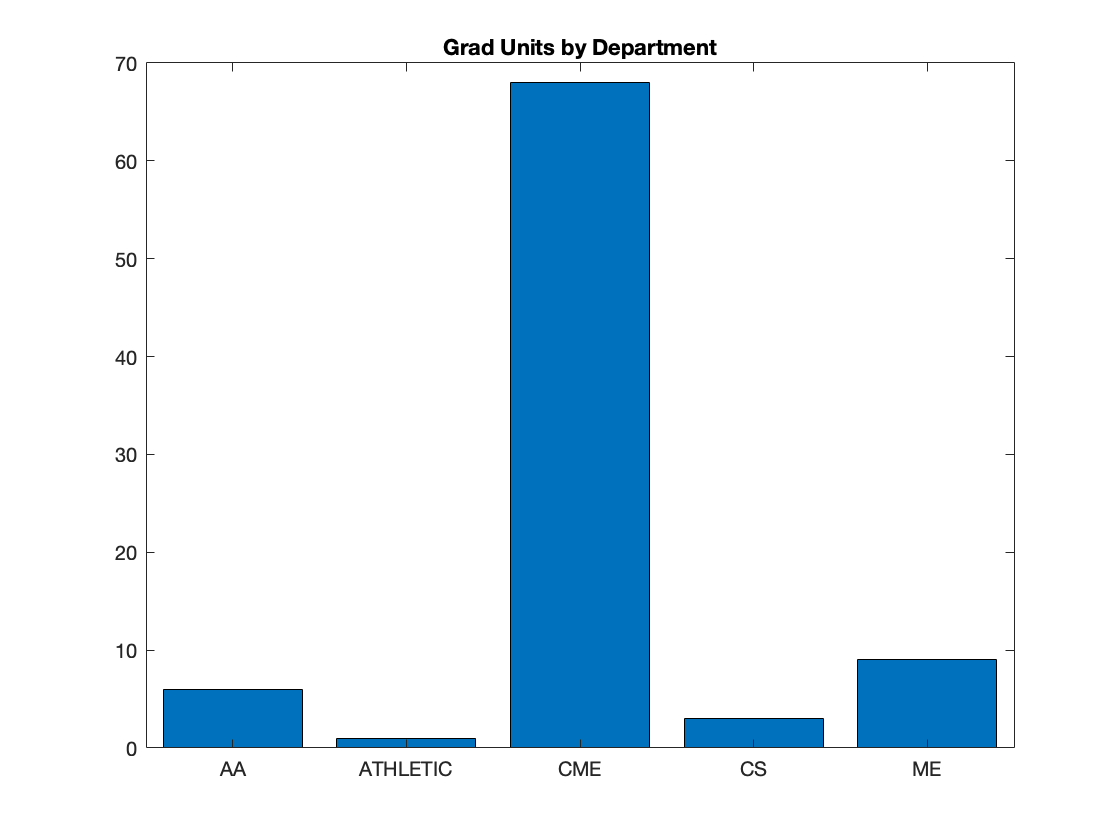


bar(deptUnits.department,deptUnits.sum_grad_units)
title("Grad Units by Department")

#### Compute total number of classes taken

height(t)

ans = 31

#### Compute total number of graduation units (includes those taken for letter grade and P/NP)

sum(t.grad_units)

ans = 87

#### Create a bar graph of GPA vs. quarter taken (Autumn, Winter, Spring, Summer) 

seasonalGPA = rowfun(@calculateGPA,t,"GroupingVariables","quarter",...
    "InputVariables",["gpa_credits","gpa_units"])

seasonalGPA = 4×3 table
    quarter    GroupCount     Var3 
    _______    __________    ______

    Autumn         12        3.1778
    Spring          7          3.52
    Summer          3             4
    Winter          9        3.1579



% reorder seasons to correspond with academic calendar
seasonalGPA = seasonalGPA([1 4 2 3],:)

seasonalGPA = 4×3 table
    quarter    GroupCount     Var3 
    _______    __________    ______

    Autumn         12        3.1778
    Winter          9        3.1579
    Spring          7          3.52
    Summer          3             4


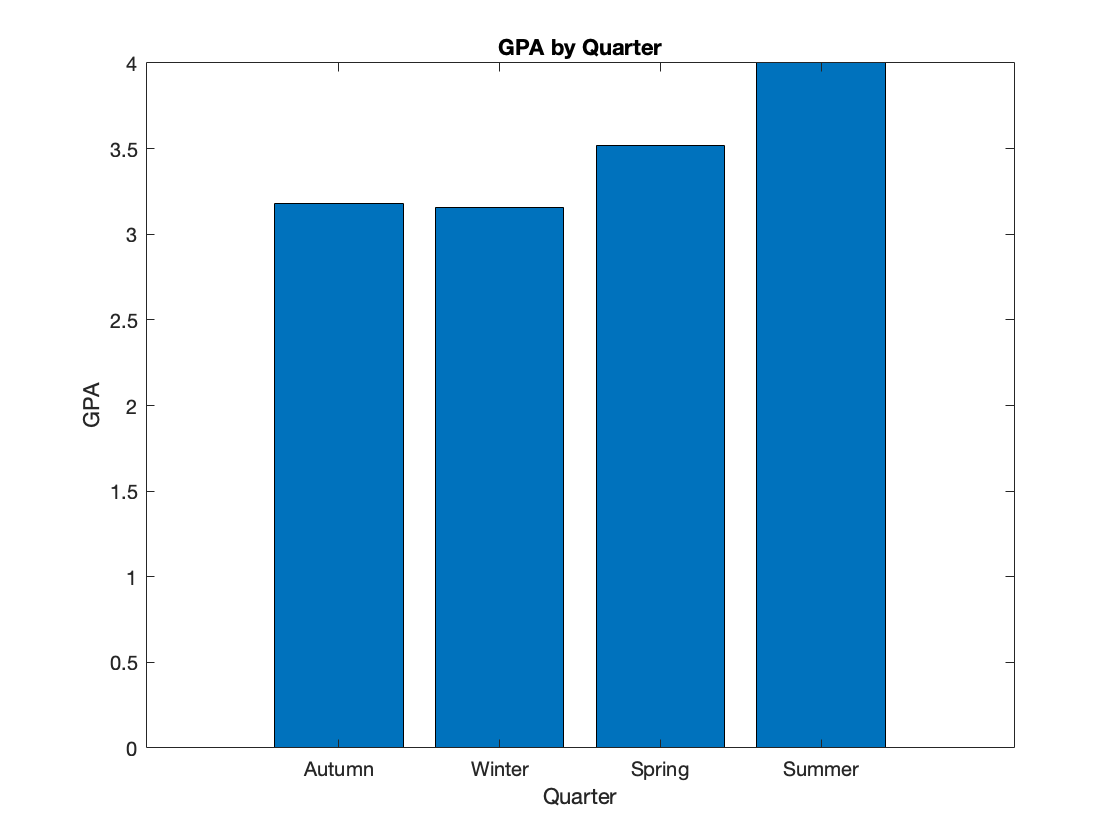


% Make the bar plot and change the tick labels
b = bar(seasonalGPA.Var3);
% Get the parent, which is the axes.
bp = b.Parent;
bp.XTickLabel = ["Autumn", "Winter", "Spring", "Summer"];
xlabel("Quarter")
ylabel("GPA")
title("GPA by Quarter")

#### Create a bar graph of GPA vs. quater *and *year in Stanford career that class was taken (1st, 2nd, ...). 

Note that we define Year 1 at Stanford as the academic year starting the *Autumn* quarter you arrived at Stanford.  Any class taken the summer before your first Autumn quarter would be considered a 0-th year. This was taken care of in `make_course_struct.m` for you.

seasonalGPA = rowfun(@calculateGPA,t,"GroupingVariables",["quarter","academic_year"],...
"InputVariables",["gpa_credits","gpa_units"])

seasonalGPA = 10×4 table
    quarter    academic_year    GroupCount     Var4 
    _______    _____________    __________    ______

    Autumn           1              4         3.6667
    Autumn           2              4            3.1
    Autumn           3              4         2.7667
    Spring           1              3         3.7667
    Spring           2              4           3.15
    Summer           0              1            3.7
    Summer           2              2            4.3
    Winter           1              3         3.3333
    Winter           2              4            3.3
    Winter           3              2            2.3


%reorder by quarter
seasonalGPA = seasonalGPA([find(seasonalGPA.quarter=='Autumn');find(seasonalGPA.quarter=='Winter');...
    find(seasonalGPA.quarter=='Spring');find(seasonalGPA.quarter=='Summer')],:)

seasonalGPA = 10×4 table
    quarter    academic_year    GroupCount     Var4 
    _______    _____________    __________    ______

    Autumn           1              4         3.6667
    Autumn           2              4            3.1
    Autumn           3              4         2.7667
    Winter           1              3         3.3333
    Winter           2              4            3.3
    Winter           3              2            2.3
    Spring           1              3         3.7667
    Spring           2              4           3.15
    Summer           0              1            3.7
    Summer           2              2            4.3


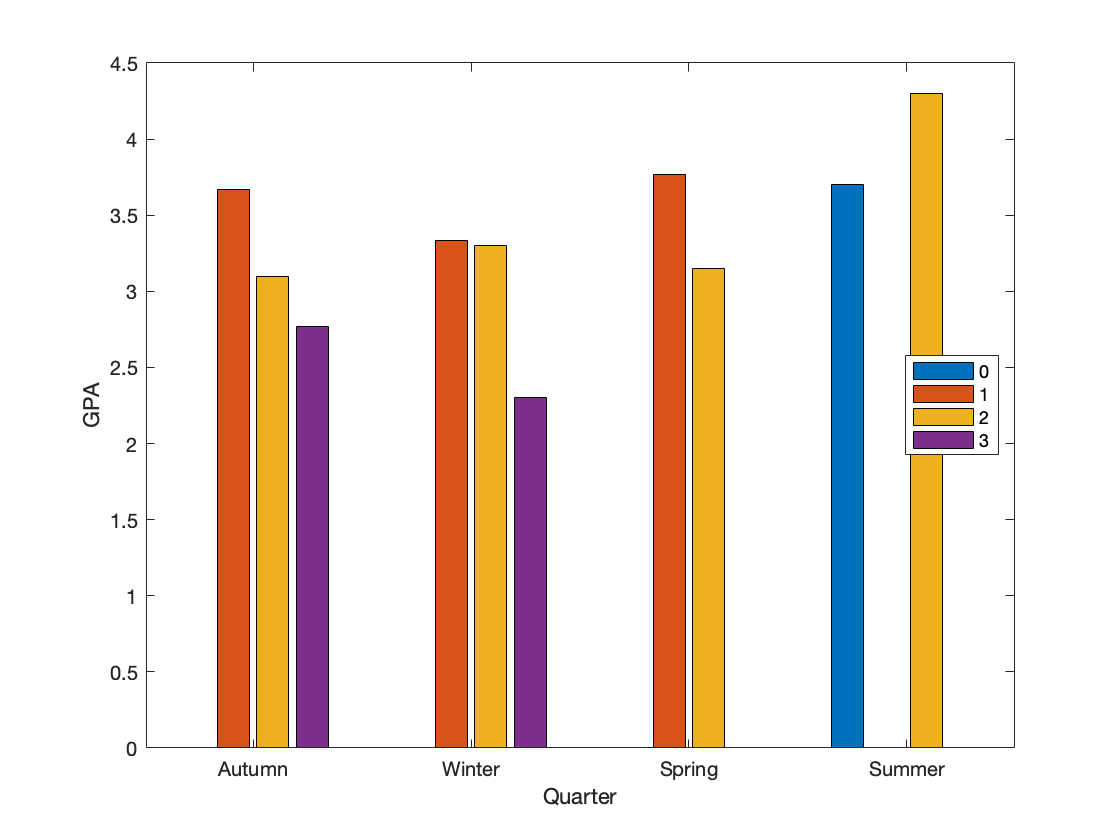

% Make the bar plot and change the tick labels
% recast in a matrix for bar plot
seasonalGPA_mat=zeros(4);
quarter={'Autumn','Winter','Spring','Summer'};
for i =1:4
    for j=1:4
        ind=find(seasonalGPA.quarter==quarter(j)&seasonalGPA.academic_year==i-1);
        if ~isempty(ind)
            seasonalGPA_mat(i,j)=seasonalGPA(ind,:).Var4;
        end
    end
end
b = bar(seasonalGPA_mat');
% Get the parent, which is the axes.
bp = b.Parent;
legend('0','1','2','3','Location','Best');
bp.XTickLabel = ["Autumn", "Winter", "Spring", "Summer"];
xlabel("Quarter")
ylabel("GPA")

#### * Function to Calculate GPA

function gpa = calculateGPA(credits,units)
    if isnan(credits)
        gpa=0;
    else
        gpa = sum(credits.* units)/sum(units);
    end
end
